clear; clc; clear

width = 1.5 ; % Line thickness
lsize = 14 ; tsize = 14 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

% AIRFOIL VARIABLES
gamma = 1.4

gamma = 1.4000

c = 1 %chord

c = 1

% Mach Numbers to be tested

M1 = [1.5:0.05:3]

M1 =     1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500    2.5000    2.5500    2.6000    2.6500    2.7000    2.7500    2.8000    2.8500    2.9000    2.9500    3.0000


%M1 = [1.5,1.7,2.2,3]

% M1 = [1.5,1.6,1.7,1.8,2,2.2,2.4,2.6,2.8,3];
%M1 = [1.3,2,3]

% Deflections to be plotted
t = 0.05; theta1 = atand(2*t./c);
cmap = colormap(lines(length(theta1)));
weak = 0 % This specifies we want the weak solution only - strong solutions are off condition

weak = 0


%Setting up the freestream inflow (this is trivial)
Pr1         = ones(length(theta1),length(M1));
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Full Ideal Solver

%preallocation
x1          = zeros(length(theta1),length(M1));
x2          = zeros(length(theta1),length(M1));
H_exact     = zeros(length(theta1),length(M1));
h_star_exact= zeros(length(theta1),length(M1));
A_ratio     = zeros(length(theta1),length(M1));
M2          = zeros(length(theta1),length(M1));
M3          = zeros(length(theta1),length(M1));
theta2      = zeros(length(theta1),length(M1));
phi1        = zeros(length(theta1),length(M1));
phi2        = zeros(length(theta1),length(M1));
Pr2         = zeros(length(theta1),length(M1));
Pr3         = zeros(length(theta1),length(M1));
beta1       = zeros(length(theta1),length(M1));
beta2       = zeros(length(theta1),length(M1));

for j = 1:length(theta1)
    theta = theta1(j);
    for i=1:length(M1)
        machno = M1(i);
[x1(j,i),x2(j,i),H_exact(j,i),h_star_exact(j,i),A_ratio(j,i),beta1(j,i),beta2(j,i),M2(j,i),M3(j,i),theta2(j,i),phi1(j,i),phi2(j,i),Pr2(j,i),Pr3(j,i)] = IdealSpacing(machno,theta,c,gamma);
    end
end

H_exact

H_exact =     0.6968    0.6240    0.5744    0.5363    0.5054    0.4795    0.4573    0.4379    0.4208    0.4055    0.3918    0.3793    0.3679    0.3575    0.3478    0.3389    0.3306    0.3229    0.3157    0.3089    0.3025    0.2965    0.2908    0.2855    0.2804    0.2756    0.2710    0.2666    0.2625    0.2585    0.2547


% Net Pressure Rise
TotalPr = Pr3.*Pr2.*Pr1;

## Plotting Spacings

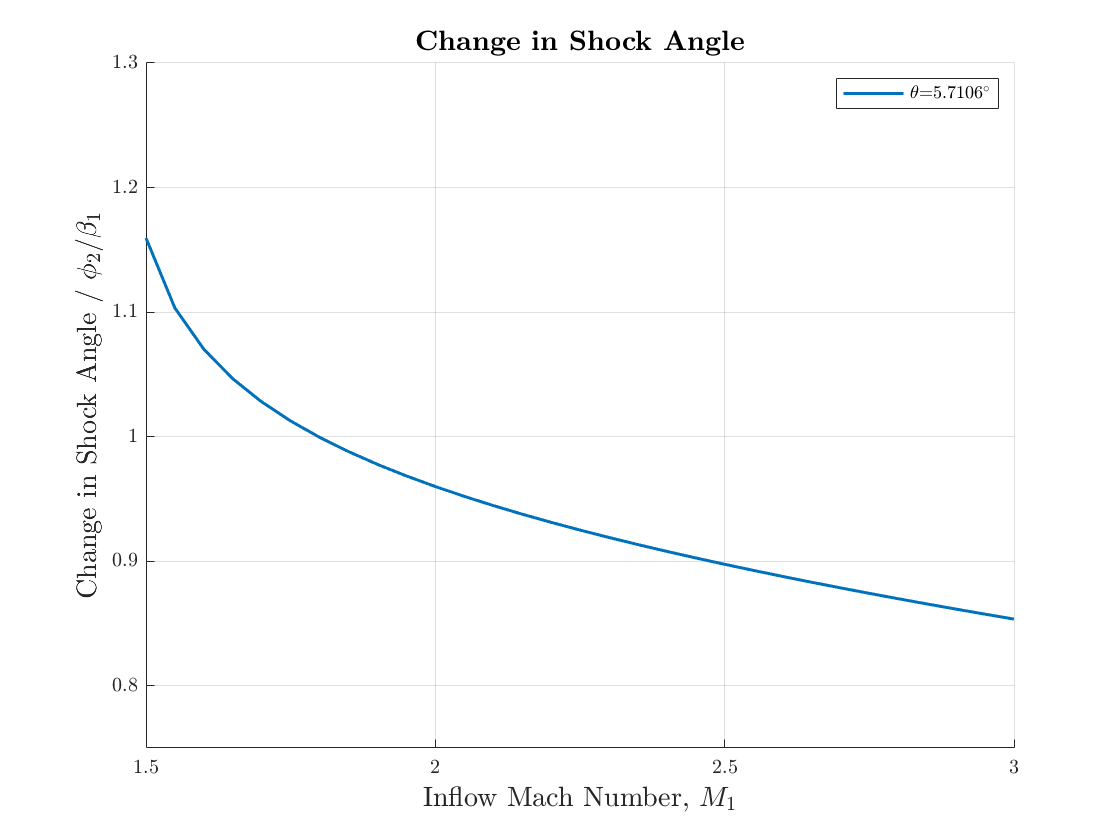

anglechange=phi2./beta1; %all correct and verified

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

figure
for line = 1:length(theta1)
plot(M1,anglechange(line,:),'-','Color',cmap(line,:),"LineWidth",width)
hold on
end
xlabel("Inflow Mach Number, $M_{1}$",'FontSize',lsize)
ylabel("Change in Shock Angle / $\phi_{2}/\beta_{1}$",'FontSize',lsize)
title("\textbf{Change in Shock Angle}",'FontSize',tsize)
legend(legendCelltheta,'FontSize',legsize)
grid on; box off
xlim([min(M1),max(M1)]); ylim([0.75,1.3])
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Kusunose et al. (2011)
Jpn_Mach = 1.7; Jpn_t = 0.05; Jpn_H = 0.505; Jpn_h = Jpn_H-(2*Jpn_t); Jpn_Ar = Jpn_h/Jpn_H;
H_exact

H_exact =     0.6968    0.6240    0.5744    0.5363    0.5054    0.4795    0.4573    0.4379    0.4208    0.4055    0.3918    0.3793    0.3679    0.3575    0.3478    0.3389    0.3306    0.3229    0.3157    0.3089    0.3025    0.2965    0.2908    0.2855    0.2804    0.2756    0.2710    0.2666    0.2625    0.2585    0.2547


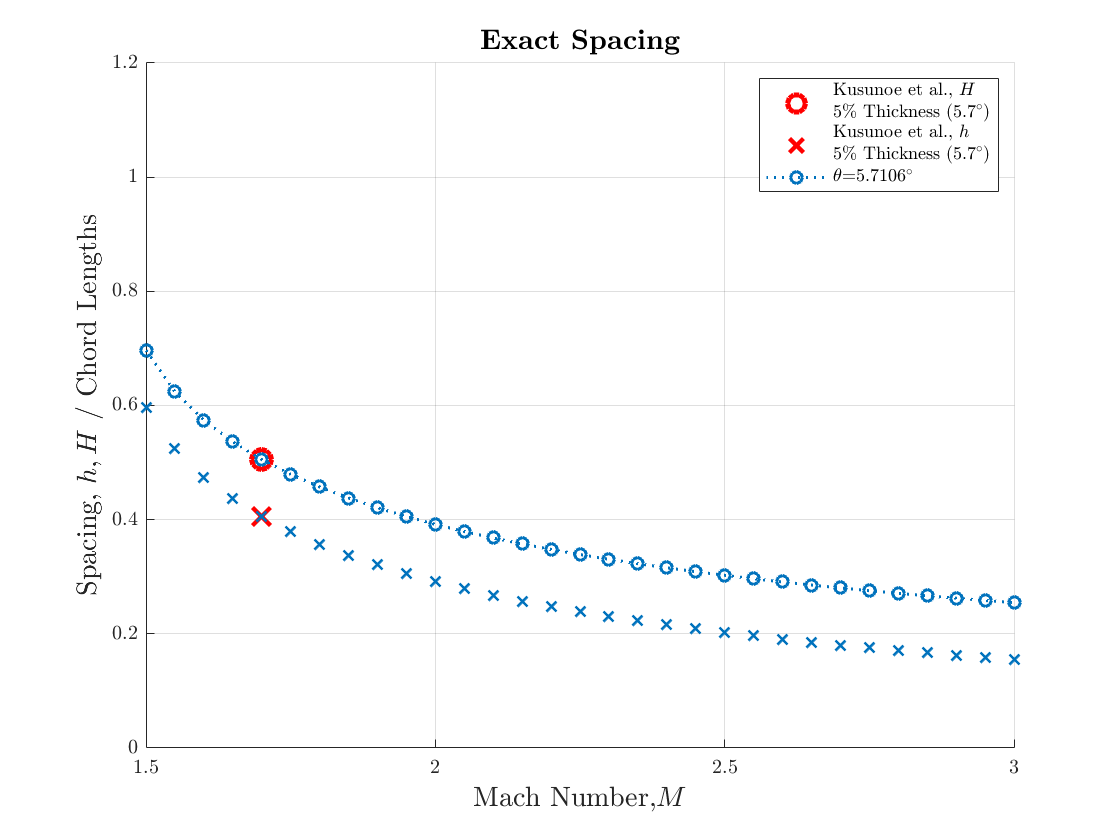


figure
%subplot(2,2,1)
plot(Jpn_Mach, Jpn_H,'or',"LineWidth",2.5,"MarkerSize",msize+2)
hold on
plot(Jpn_Mach, Jpn_h,'xr',"LineWidth",2.5,"MarkerSize",msize+2)
for line = 1:length(theta1)
plot(M1,H_exact(line,:),'o:','Color',cmap(line,:),"LineWidth",width)
hold on
end
xlabel("Mach Number,$M$",'FontSize',lsize)
ylabel("Spacing, $h,H$ / Chord Lengths",'FontSize',lsize)
for line = 1:length(theta1)
plot(M1,h_star_exact(line,:),'x','Color',cmap(line,:),"LineWidth",width)
hold on
end
title("\textbf{Exact Spacing}",'FontSize',tsize)
legend([{['Kusunoe et al., $H$' newline '5\% Thickness (5.7$^{\circ}$)']},{['Kusunoe et al., $h$' newline '5\% Thickness (5.7$^{\circ}$)']},legendCelltheta],'location','northeast','FontSize',legsize)
grid on; box off
xlim([min(M1),max(M1)]); ylim([0.0,1.2]);

## Choking and Area Ratio

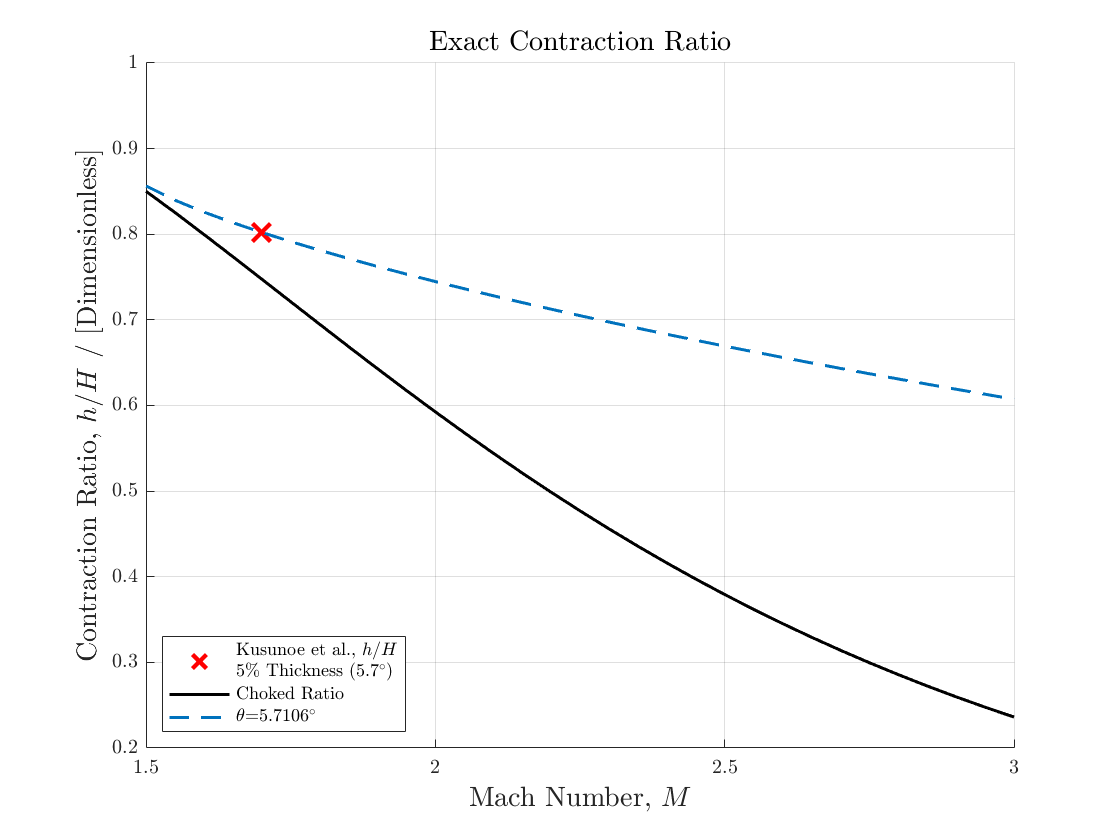

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Chocked_Area=zeros(1,length(M1));
for n=1:length(M1)
    Chocked_Area(n) = 1./Area_Ratio(M1(n),gamma);
end

figure
%subplot(2,2,2)
plot(Jpn_Mach, Jpn_Ar,'xr',"LineWidth",2.5,"MarkerSize",msize+2)
hold on
plot(M1,Chocked_Area,'k',"LineWidth",width)
for line = 1:length(theta1)
    plot(M1,A_ratio(line,:),'--','Color',cmap(line,:),"LineWidth",width)
    hold on
end
xlabel("Mach Number, $M$",'FontSize',lsize)
ylabel("Contraction Ratio, $h/H$ / [Dimensionless]",'FontSize',lsize)
title("Exact Contraction Ratio",'FontSize',tsize)
legend([{['Kusunoe et al., $h/H$' newline '5\% Thickness (5.7$^{\circ}$)']},"Choked Ratio",legendCelltheta],'Location','southwest','FontSize',legsize)
grid on; box off
xlim([min(M1),max(M1)]); ylim([0.2,1.0])

## Initial Expansion

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Flow field at the central point: M3
% Relative direction = 0deg, turn = theta1
M3(M3 < 1) = NaN; %Gets rid of the subsonic central regioned pts
M3

M3 =     1.0460    1.1259    1.1907    1.2491    1.3039    1.3564    1.4071    1.4565    1.5049    1.5525    1.5993    1.6455    1.6912    1.7365    1.7813    1.8257    1.8697    1.9134    1.9569    2.0000    2.0428    2.0854    2.1278    2.1698    2.2117    2.2533    2.2948    2.3360    2.3770    2.4178    2.4584


mu1 = asind(1./M3);
phi_startExp = mu1 %apex expansion starting angle, deg

phi_startExp =    72.9459   62.6408   57.1243   53.1840   50.0769   47.4984   45.2903   43.3588   41.6429   40.1008   38.7019   37.4236   36.2480   35.1615   34.1527   33.2123   32.3329   31.5079   30.7319   30.0003   29.3088   28.6541   28.0330   27.4428   26.8810   26.3456   25.8346   25.3462   24.8790   24.4314   24.0022



v_M4 = transpose(theta1)+PrandtlMeyer(M3,gamma);
M4 = InvPrandtlMeyer(v_M4); % machs after the first expansion
mu2 = asind(1./M4);
phi_endExp = mu2-transpose(theta1) %apex expansion end angle, deg

phi_endExp =    44.6298   42.0694   39.7949   37.7898   36.0022   34.3922   32.9296   31.5917   30.3607   29.2223   28.1652   27.1798   26.2583   25.3940   24.5812   23.8151   23.0914   22.4064   21.7569   21.1400   20.5532   19.9941   19.4608   18.9514   18.4643   17.9980   17.5511   17.1224   16.7107   16.3150   15.9345


%phi is relative to the horizontal 

%yes these angles are right

## Fast Method of Expansions

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% This essentially breaks the expansions down into three length
% x3 = distance covered to meet at the centerline 
% F1, distance travelled for expansion head wave to hit other side
% F2, distnace travelled for rtail wave to hit other side
% if all works out then this distance (F2) shoucl be
% half a chord length.

% THIS FAST METHOD DOES NOT ACCOUNT FOR EXPANSION-EXPANSION INTERACTION

% x3 - intersection point
x_3 = (h_star_exact/2)./tand(phi_startExp);

% F2
F2 = (H_exact-transpose(t)).*tand(90-phi_endExp);
%Overexpansion_length 

Lk= F2-0.5;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% F1
F1 = (h_star_exact.*tand(90-phi_startExp)) ./ (1-(2.*transpose(t)).*tand(90-phi_startExp));
%F1 = (h_star_exact.*tand(90-phi_startExp)) ./
%(1-(tand(theta).*tand(90-phi_startExp))) %same alternative

## AREA RATIO METHOD

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% So here we have an expansion from A1 to A2 i.e. h to H
% This equates to a mach increase (or should) from M3 to M5
% We use a supersonic (chocked) reference condion: (A2/A*) = (A2/A1)(A1/A*)

%(A2/A1)
Overall_Exp_Ratio = H_exact./h_star_exact;

%(A1/A*)
Start_Mach_ARatio = Area_Ratio(M3,gamma);

% The calculation
Final_Mach_ARatio = Overall_Exp_Ratio.*Start_Mach_ARatio;

M5_AR = zeros(size(M3));

for i = 1:length(theta1)
    for j = 1:length(M1)
M5_AR(i,j) = Inv_Area_Ratio(Final_Mach_ARatio(i,j),gamma);
    end 
end

Recovery_MachRatio_AR = 100*(M5_AR./M1);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Inital Drag Calculations

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Renaming due to earlier flaws
P1 = Pr1;
P2 = Pr2;
P3 = TotalPr;
% We can obtain the pressures of the expansions as such
P4 = isentropicPr(M3,M4,P3,gamma);

%angle to the end of the airfoil
phi_startExp

phi_startExp =    72.9459   62.6408   57.1243   53.1840   50.0769   47.4984   45.2903   43.3588   41.6429   40.1008   38.7019   37.4236   36.2480   35.1615   34.1527   33.2123   32.3329   31.5079   30.7319   30.0003   29.3088   28.6541   28.0330   27.4428   26.8810   26.3456   25.8346   25.3462   24.8790   24.4314   24.0022


c=1; phi_rear = 90-(atand((0.5*c)./(h_star_exact+t)))

phi_rear =    52.2967   48.9425   46.3665   44.2065   42.3295   40.6644   39.1672   37.8073   36.5627   35.4166   34.3557   33.3696   32.4496   31.5885   30.7802   30.0195   29.3021   28.6239   27.9818   27.3726   26.7938   26.2430   25.7182   25.2175   24.7392   24.2818   23.8439   23.4243   23.0217   22.6353   22.2639


phi_endExp

phi_endExp =    44.6298   42.0694   39.7949   37.7898   36.0022   34.3922   32.9296   31.5917   30.3607   29.2223   28.1652   27.1798   26.2583   25.3940   24.5812   23.8151   23.0914   22.4064   21.7569   21.1400   20.5532   19.9941   19.4608   18.9514   18.4643   17.9980   17.5511   17.1224   16.7107   16.3150   15.9345


%modify start and end
       a_i =      0.9896

a_i = 0.9896

       b_i =     0.04441

b_i = 0.0444

       c_i =         -30

c_i = -30

       d_i =      -3.589

d_i = -3.5890

f = @(x) a_i*exp(b_i*x) + c_i*exp(d_i*x)

f = function_handle with value:
    @(x)a_i*exp(b_i*x)+c_i*exp(d_i*x)


phi_startExpa = f(M1).*phi_startExp %0.95 going to 

phi_startExpa =    67.1113   59.1953   55.1972   52.3559   50.0772   48.1357   46.4235   44.8812   43.4729   42.1749   40.9707   39.8481   38.7977   37.8120   36.8848   36.0107   35.1854   34.4048   33.6654   32.9641   32.2982   31.6650   31.0624   30.4881   29.9404   29.4174   28.9176   28.4395   27.9818   27.5431   27.1225


%phi_startExpa = [67 50 37 27]

       p1 =     0.01832

p1 = 0.0183

       p2 =    -0.09176

p2 = -0.0918

       p3 =      0.1778

p3 = 0.1778

       p4 =       0.798

p4 = 0.7980

f = @(x) p1*x.^3 + p2*x.^2 + p3*x + p4

f = function_handle with value:
    @(x)p1*x.^3+p2*x.^2+p3*x+p4


phi_endExpa = f(M1).*phi_endExp %increasing to 1

phi_endExpa =    41.0625   38.7610   36.7153   34.9120   33.3049   31.8581   30.5448   29.3448   28.2422   27.2245   26.2815   25.4049   24.5878   23.8242   23.1091   22.4384   21.8082   21.2153   20.6569   20.1303   19.6334   19.1642   18.7208   18.3017   17.9053   17.5303   17.1755   16.8399   16.5223   16.2218   15.9377


%phi_endExpa = [41 33 23 16]
phi_inter=phi_startExpa-phi_endExpa

phi_inter =    26.0488   20.4343   18.4819   17.4439   16.7723   16.2776   15.8786   15.5364   15.2307   14.9504   14.6892   14.4432   14.2100   13.9879   13.7756   13.5724   13.3772   13.1895   13.0086   12.8338   12.6648   12.5009   12.3416   12.1865   12.0351   11.8871   11.7421   11.5996   11.4595   11.3213   11.1848


phi_proportion = (phi_startExpa-phi_rear)./(phi_inter)

phi_proportion =     0.5687    0.5017    0.4778    0.4672    0.4619    0.4590    0.4570    0.4553    0.4537    0.4521    0.4503    0.4485    0.4467    0.4449    0.4431    0.4414    0.4398    0.4383    0.4369    0.4357    0.4346    0.4337    0.4330    0.4325    0.4322    0.4320    0.4321    0.4324    0.4328    0.4335    0.4344


flow_angle_rear = phi_proportion.*transpose(theta1)

flow_angle_rear =     3.2478    2.8653    2.7285    2.6679    2.6379    2.6211    2.6097    2.6001    2.5909    2.5815    2.5717    2.5615    2.5511    2.5408    2.5306    2.5208    2.5115    2.5029    2.4950    2.4880    2.4820    2.4769    2.4728    2.4698    2.4679    2.4671    2.4675    2.4690    2.4717    2.4756    2.4806



%partly expanded
%v_rear = flow_angle_rear+PrandtlMeyer(M4,gamma); %as we are going from condition 4
    %M_rear = InvPrandtlMeyer(v_rear);
    %P_rear = isentropicPr(M4,M_rear,P4,gamma);
%fully expanded - as much as can be
v_M5 = transpose(theta1)+PrandtlMeyer(M4,gamma);
    M5 = InvPrandtlMeyer(v_M5)

M5 =     1.4982    1.5466    1.5964    1.6463    1.6963    1.7463    1.7963    1.8462    1.8961    1.9461    1.9960    2.0458    2.0957    2.1456    2.1954    2.2452    2.2950    2.3448    2.3946    2.4444    2.4941    2.5439    2.5936    2.6433    2.6929    2.7426    2.7922    2.8419    2.8915    2.9411    2.9906


    P5 = isentropicPr(M4,M5,P4,gamma)

P5 =     0.9969    1.0000    1.0007    1.0008    1.0009    1.0009    1.0008    1.0008    1.0007    1.0007    1.0006    1.0006    1.0005    1.0005    1.0004    1.0004    1.0003    1.0003    1.0002    1.0002    1.0002    1.0002    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0002    1.0002



%F1
%F1 = (h_star_exact.*tand(90-phi_startExpa))./(1-(tand(theta1).*tand(90-phi_startExpa)))
%Lenth_inthe_fan 
%q = 0.5-F1
%amount_at_P4
%l4 = F1./cosd(transpose(theta1))% this is at P4
%lv = q./(cosd(transpose(theta1))) %sqrt(t.^2+(c/2).^2) - l4; % this is at a variable Pressure
       a_i =   1.454e+07

a_i = 14540000

       b_i =      -12.63

b_i = -12.6300

       c_i =      0.1447

c_i = 0.1447

       d_i =    -0.04892

d_i = -0.0489

f = @(x) a_i*exp(b_i*x) + c_i*exp(d_i*x)

f = function_handle with value:
    @(x)a_i*exp(b_i*x)+c_i*exp(d_i*x)


%actual Amount_covered
lv = f(M1) %[0.44 0.28 0.26 0.25]*0.5

lv =     0.2205    0.1799    0.1581    0.1464    0.1400    0.1365    0.1344    0.1332    0.1324    0.1318    0.1314    0.1310    0.1306    0.1303    0.1299    0.1296    0.1293    0.1290    0.1287    0.1284    0.1280    0.1277    0.1274    0.1271    0.1268    0.1265    0.1262    0.1259    0.1256    0.1253    0.1249



% Pressure at end
P4

P4 =     1.3194    1.3234    1.3259    1.3290    1.3328    1.3373    1.3423    1.3478    1.3537    1.3599    1.3664    1.3732    1.3802    1.3873    1.3947    1.4022    1.4099    1.4177    1.4257    1.4338    1.4420    1.4503    1.4587    1.4673    1.4759    1.4846    1.4935    1.5024    1.5114    1.5204    1.5296


proportion_exp_onsurface = phi_proportion %0.5-0.65 works well

proportion_exp_onsurface =     0.5687    0.5017    0.4778    0.4672    0.4619    0.4590    0.4570    0.4553    0.4537    0.4521    0.4503    0.4485    0.4467    0.4449    0.4431    0.4414    0.4398    0.4383    0.4369    0.4357    0.4346    0.4337    0.4330    0.4325    0.4322    0.4320    0.4321    0.4324    0.4328    0.4335    0.4344


Pv =((1-proportion_exp_onsurface).*P4)+(proportion_exp_onsurface.*P5)

Pv =     1.1360    1.1612    1.1705    1.1757    1.1795    1.1829    1.1863    1.1898    1.1936    1.1975    1.2017    1.2060    1.2106    1.2152    1.2200    1.2248    1.2298    1.2348    1.2398    1.2449    1.2500    1.2551    1.2602    1.2652    1.2703    1.2753    1.2803    1.2852    1.2901    1.2949    1.2996


P5

P5 =     0.9969    1.0000    1.0007    1.0008    1.0009    1.0009    1.0008    1.0008    1.0007    1.0007    1.0006    1.0006    1.0005    1.0005    1.0004    1.0004    1.0003    1.0003    1.0002    1.0002    1.0002    1.0002    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0002    1.0002


%fudge factors take into account the fact that the pressure is closer to
%P_rear than P4... admittidly this changes a bit though

% Dynamic Head in terms of 1/P_inf
q_inf = 0.5*gamma*P1.*M1.^2;

% Associated Pressure coefficients
Cp1 = P1.*(P1-1)./q_inf;
Cp2 = P1.*(P2-1)./q_inf;
Cp3 = P1.*(P3-1)./q_inf;
Cp4 = P1.*(P4-1)./q_inf;
Cpv = P1.*(Pv-1)./q_inf;
%Cp5 = P1.*(P5-1)./q_inf;

% Associated Lengths for Drag
l2 = sqrt(t.^2+(c/2).^2);
l4=l2-lv;
%alternative(old method)
P5a = isentropicPr(M4,M5_AR,P4,gamma); %(Assumed we can scale with the Mach number of outflow) 
Pva = 0.5*(P4+P5);
%l4 = F1./transpose(cosd(theta1))
%lv = F2./transpose(cosd(theta1));

% Area
% Unsure if to use projected, planform or a thickness based assumption
% Area = 2*t
Area = 1; %Unit area - PLANFORM i.e. one surface only

% Total Drag
Drag = 2*P1.*transpose(sind(theta1)).*((transpose(l2).*P2)-((l4.*P4)+(lv.*Pv)));
%Draga = 2*P1.*transpose(sind(theta1)).*((transpose(l2).*P2)-((l4.*P4)+(lv.*Pva)));

% Total Cd
Cd = Drag./(q_inf.*transpose(Area))

Cd =     0.0054    0.0035    0.0027    0.0023    0.0021    0.0019    0.0018    0.0017    0.0017    0.0016    0.0015    0.0015    0.0014    0.0014    0.0013    0.0013    0.0012    0.0012    0.0012    0.0011    0.0011    0.0011    0.0011    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009


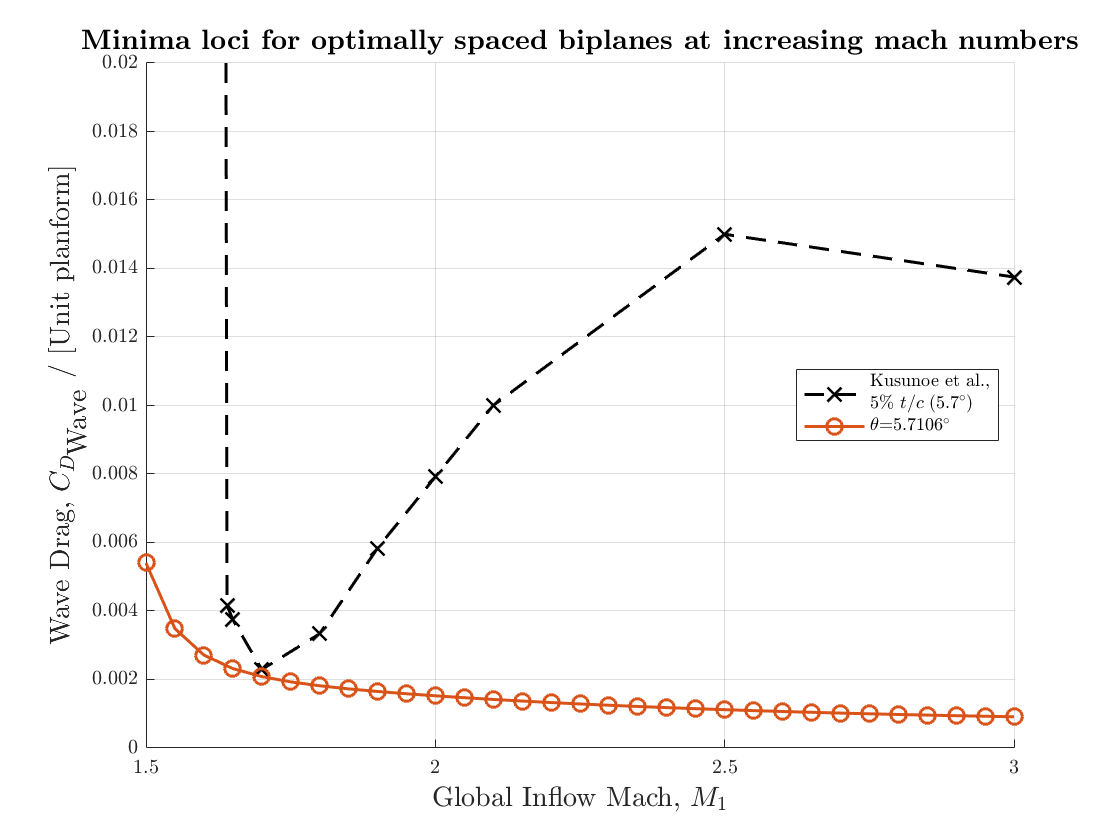

%Cda = Draga./(q_inf.*transpose(Area))
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PLOTTING WAVE

% KUSUNOSE  - Supersonic biplane—A review

%FIG 18 - cdwave across machs for 4 different airfoils
%busemann		diamond airfoil		morphing		fowler
Kusunose_review_fig18_buseman_machs=[0.3,0.5,0.55,0.6,0.65,0.7,0.75,0.8,0.85,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.62,1.63,1.64,1.65,1.7,1.8,1.9,2,2.1,2.5,3];
Kusunose_review_fig18_buseman_cd=[0.001041667,0.003333333,0.023333333,0.071666667,0.10625,0.130833333,0.147916667,0.1475,0.1375,0.129166667,0.117083333,0.109166667,0.104166667,0.100208333,0.097083333,0.094791667,0.092916667,0.0925,0.092291667,0.004166667,0.00375,0.002291667,0.003333333,0.005833333,0.007916667,0.01,0.015,0.01375];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Kusunose et al. (2011)
MachRuns_buse = Kusunose_review_fig18_buseman_machs;
Jpn_Busemann = Kusunose_review_fig18_buseman_cd;

% Japanese point performance Drag Results: 
% Optimal Point
figure
plot(MachRuns_buse,Jpn_Busemann,'x--k',"LineWidth",width,"MarkerSize",8)
%plot(Jpn_Mach,Jpn_CDWave,'xk',"LineWidth",1.5)
hold on
for line = 1:length(theta1)
plot(M1,Cd(line,:),'o-',"LineWidth",width,"MarkerSize",8)
%plot(M1,Cda(line,:),'o-',"LineWidth",width,"MarkerSize",8)
hold on
end

formatSpec = '%.2f';
legendCelltheta = strcat('$\theta$=',string(num2cell(theta1)),'$^{\circ}$');
legendCell = strcat('($t/c$=',string(num2cell(100*t)),'\%)');

legend([{['Kusunoe et al.,' newline '5\% $t/c$ (5.7$^{\circ}$)']},legendCelltheta],'location','east','FontSize',legsize)
xlabel("Global Inflow Mach, $M_{1}$",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Minima loci for optimally spaced biplanes at increasing mach numbers}",'FontSize',tsize)
grid on
ylim([0,0.02])
xlim([min(M1),max(M1)])
box off
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
SE_mach = M1;
SE_cdwave = Cd;
%SEa_cdwave = Cda;
SE_spacing = H_exact;

% Vs foam
oldfoam_mach = [1.5,1.6,1.7,1.8,2,2.2,2.4,2.6,2.8,3];
oldfoam_cdwave = [0.00428408,0.00309546,0.00234688,0.00217738,0.00193102,0.00178917,0.00172647,...
0.00169135,0.00164138,0.00173464];
%oldfoam_spacing=[0.6968,0.5744,0.5054,0.4573,0.3918,0.3478,0.3157,0.2908,0.2710,0.2547];
%oldfoam_cellcount = [23512,21122,20026,19618,18368,18192,17780,17606,17166,16744];

newfoam_mach = [1.5,1.6,1.7,1.8,2,2.2,2.4,2.6,2.8,3];
newfoam_cdwave = [0.00401168,0.00265670,0.00215534,0.00188625,...
0.00153404,0.00143431,0.00133589,0.00127382,0.00125071,0.00118717]

newfoam_cdwave =     0.0040    0.0027    0.0022    0.0019    0.0015    0.0014    0.0013    0.0013    0.0013    0.0012


newfoam_spacing=[0.6968,0.5744,0.5054,0.4573,0.3918,0.3478,0.3157,0.2908,0.2710,0.2547];
newfoam_cellcount = [21140,21404,21388,21156,21514,21026,21248,21346,21178,21284];

Mimimium_Kusunose = Jpn_Busemann(22)

Mimimium_Kusunose = 0.0023

Theorietical_Optimal = Cd(5)%5

Theorietical_Optimal = 0.0021

%oldMimimium_FOAM= oldfoam_cdwave(3)
newMimimium_FOAM= newfoam_cdwave(3)

newMimimium_FOAM = 0.0022

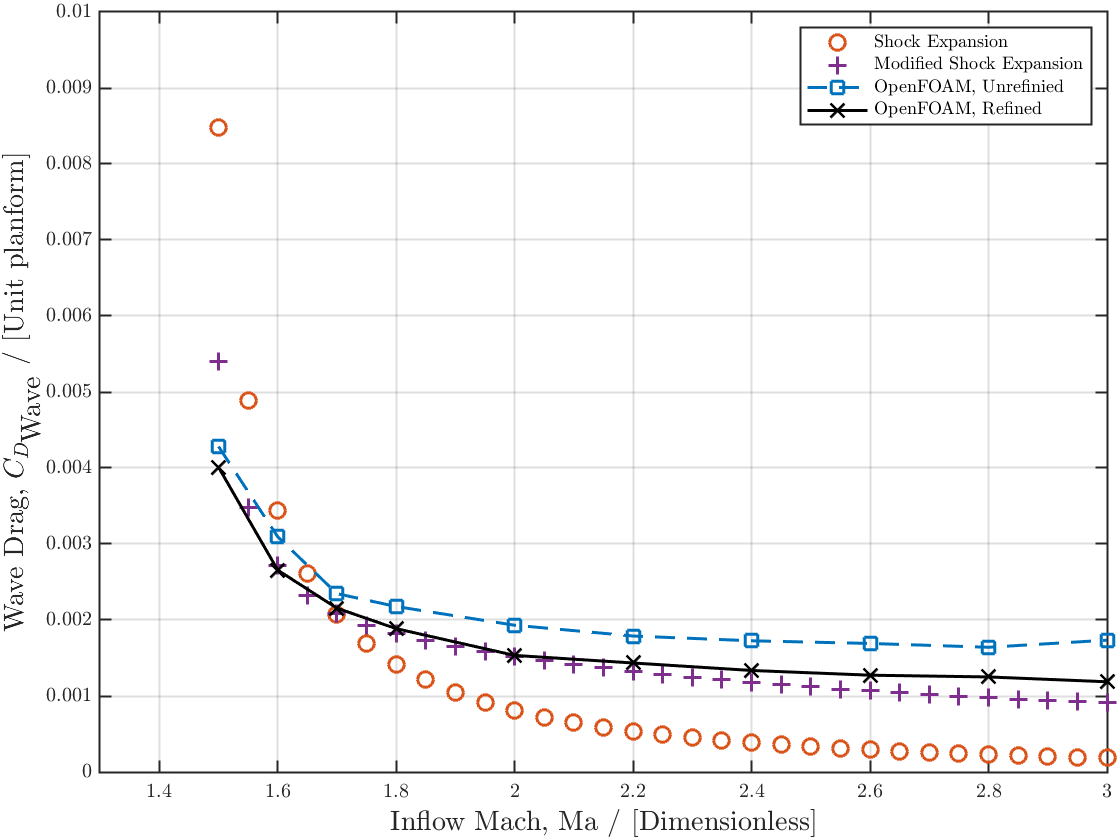


SE_cdwaveold = [0.008482519 0.004894208 0.003440904 0.00261172 0.002073198 0.001696909 0.001420898 0.001211175 0.001047436 0.000916787 0.000810652 0.00072311 0.000649955 0.000588118 0.000535314 0.000489814 0.000450282 0.000415679 0.00038518 0.00035813 0.000333996 0.000312347 0.000292828 0.000275146 0.000259057 0.000244358 0.000230874 0.000218462 0.000206996 0.000196371 0.000186495];

figure
plot(SE_mach,SE_cdwaveold,'o',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
hold on
plot(SE_mach,SE_cdwave,'+',"LineWidth",1.5,"MarkerSize",msize,"Color",purple)
plot(oldfoam_mach,oldfoam_cdwave,'s--',"LineWidth",1.5,"MarkerSize",msize,'Color',blue)
plot(oldfoam_mach,newfoam_cdwave,'x-',"LineWidth",1.5,"MarkerSize",msize,'Color',black)
legend('Shock Expansion','Modified Shock Expansion',...
    'OpenFOAM, Unrefinied','OpenFOAM, Refined','location',...
    'northeast','FontSize',legsize)
xlabel("Inflow Mach, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
%title("\textbf{Convergence of minima loci for optimally spaced biplane ($t/c=5\%$)}",'FontSize',tsize)
ylim([0,0.01]) %0.01])
xlim([1.3, 3])
InSet = get(gca, 'TightInset');
grid on; hold off; box on
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

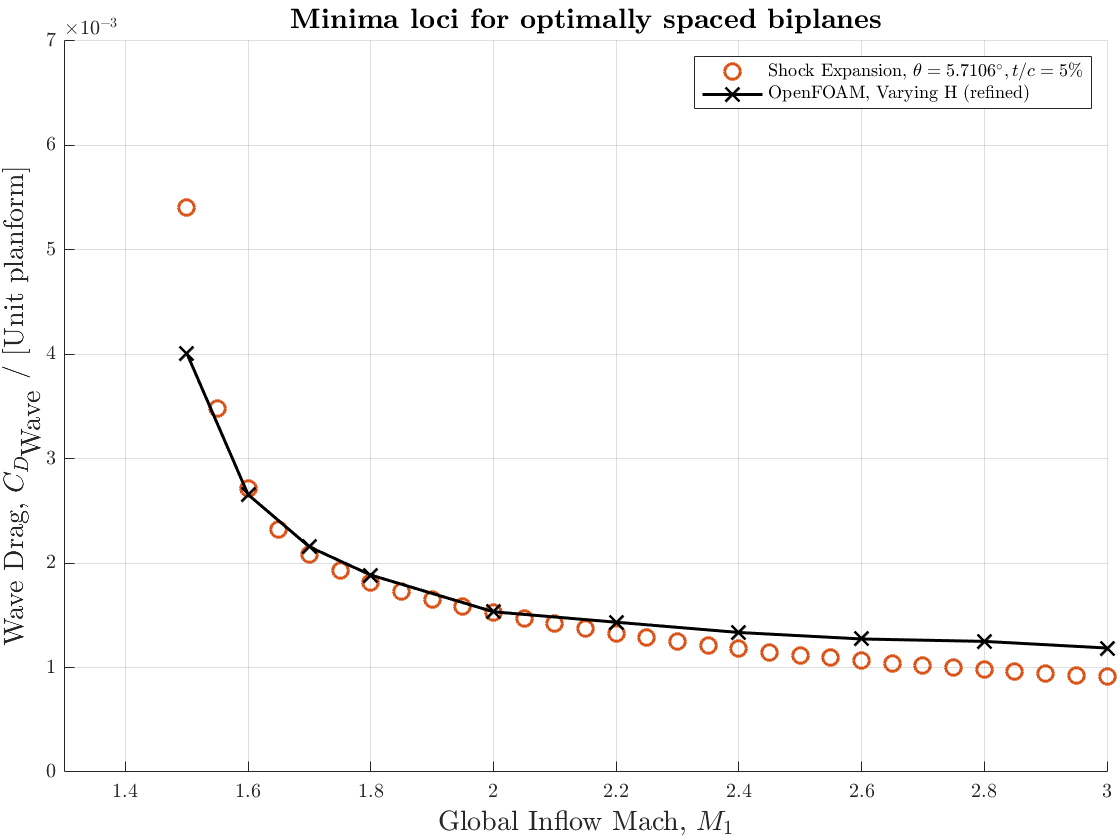


figure
%plot(MachRuns_buse,Jpn_Busemann,'x--k',"LineWidth",width,"MarkerSize",8)
%plot(Jpn_Mach,Jpn_CDWave,'xk',"LineWidth",1.5)
hold on
plot(SE_mach,SE_cdwave,'o',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
%plot(SE_mach,SEa_cdwave,'o',"LineWidth",1.5,"MarkerSize",msize,"Color",yellow)
plot(oldfoam_mach,newfoam_cdwave,'kx-',"LineWidth",1.5,"MarkerSize",msize)
legend('Shock Expansion, $\theta= 5.7106^{\circ}, t/c=5\%$','OpenFOAM, Varying H (refined)','location','northeast','FontSize',legsize)
xlabel("Global Inflow Mach, $M_{1}$",'FontSize',lsize)
ylabel("Wave Drag, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
title("\textbf{Minima loci for optimally spaced biplanes}",'FontSize',tsize)
ylim([0,0.007]) %0.01])
xlim([1.3, 3])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]); grid on; box off;hold off


% SE_cdmasqr=SE_cdwave.*(SE_mach.^2);
% foam_cdmasqr=foam_cdwave.*(foam_mach.^2);
% 
% figure
% %plot(MachRuns_buse,Jpn_Busemann,'x--k',"LineWidth",width,"MarkerSize",8)
% %plot(Jpn_Mach,Jpn_CDWave,'xk',"LineWidth",1.5)
% hold on
% plot(SE_mach,SE_cdmasqr,'o',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
% %plot(SE_mach,SEa_cdwave,'o',"LineWidth",1.5,"MarkerSize",msize,"Color",yellow)
% plot(foam_mach,foam_cdmasqr,'kx-',"LineWidth",1.5,"MarkerSize",msize)
% legend('Shock Expansion, $\theta= 5.7106^{\circ}, t/c=5\%$','OpenFOAM, Varying Spacing','location','northeast','FontSize',legsize)
% xlabel("Global Inflow Mach, $M_{1}$",'FontSize',lsize)
% ylabel("$C_{D_\textrm{Wave}}\times\textrm{Ma}^2$ / [Unit planform]",'FontSize',lsize)
% title("\textbf{Minima loci for optimally spaced biplanes}",'FontSize',tsize)
% %ylim([0,0.01])
% xlim([1.3, 3])
% InSet = get(gca, 'TightInset');
% set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]); grid on; box off;hold off


function Area = Area_Ratio(M,gamma)
% This function returns the Area (expansion) Ratio required to expand a flow
% from the sonic line for a given Mach number (M) ratio of specific heats
% (gamma). This finds it uses in rocket nozzles hence we invert it
% elsewhere in the code.

a=0.5*(gamma+1);
b=(gamma+1)/(2*(gamma-1));
c=1+((0.5*(gamma-1))*M.^2);

Area = (a^-b).*((c.^b)./M);
end

function Mach = Inv_Area_Ratio(AreaRatio,gamma)
if isnan(AreaRatio) == true
    Mach = NaN;
else
% SUPERSONIC COLUTION METHOD YIELDED
% Based on Root Finding Methods by: JoshTheEngineer
% (www.joshtheengineer.com)
%  - Solve the Area-Mach Number equation for Mach number
g   = gamma;
gm1 = g-1;
gp1 = g+1;

% Define anonymous function with two inputs (M and ARatio)
% - Pass M and ARatio as arguments to AM_EQN to get function value
% -     funVal = AM_EQN(M,ARatio)
%AM_EQN = @(M,ARatio) sqrt((1/M^2)*(((2+gm1*M^2)/gp1)^(gp1/gm1)))-ARatio;

% Solve for Msub and Msup using this area ratio (A/A*)
ARatio = AreaRatio;

% Error tolerance
%errTol = 1e-4;

%% MATLAB SOLVER

% Set up the solver
problem.objective = @(M) (1/M^2)*(((2+gm1*M^2)/gp1)^(gp1/gm1))-ARatio^2;    % Objective function
problem.solver    = 'fzero';              % Find the zero
problem.options   = optimset(@fzero);     % Default options

% Solve subsonic root
problem.x0 = [1e-6 1];              % Subsonic solver bounds
Msub       = fzero(problem);        % Solve for subsonic M
problem.x0 = [1+1e-6 50];           % Supersonic solver bounds
Msup       = fzero(problem);        % Solve for supersonic M

% Print solutions to command window
% fprintf('==== MATLAB SOLVER ====\n');
% fprintf('Msub: %3.4f\n',Msub);
% fprintf('Msup: %3.4f\n',Msup);
% fprintf('=======================\n\n');
Mach = Msup;
end
end

function [x1,x2,H_exact,h_star_exact,A_ratio,beta1,beta2,M2,M3,theta2,phi1,phi2,Pr2,Pr3]=IdealSpacing(M1,theta1,chord,gamma)

% STEP 1
t = (chord*0.5)*tand(theta1);

% STEP 2
[beta1,M2,Pr2] = ObliqueShock(M1,theta1,gamma);
%[beta1,M2,Pr2,P0r2,rhor2,tr2,M1n,M2n] = ObliqueShock(M1,theta1,gamma);
phi1 = beta1-theta1;

% STEP 3
theta2=theta1;
[beta2,M3,Pr3] = ObliqueShock(M2,theta2,gamma);
%[beta2,M3,Pr3,P0r3,rhor3,Tr3,M2n,M3n] = ObliqueShock(M2,theta2,gamma);
phi2 = beta2-theta2;

% STEP 4
alpha = 180-beta2-phi1;

% STEP 5
L = sqrt( ((0.5*chord)^2) + (t^2) );
r = (L/sind(alpha)) * sind(beta2); %sine rule

% STEP 6
x1 = r*cosd(beta1);
x2 = (0.5*chord)-x1;
dy = r*sind(beta1);

% STEP 7
H_exact = 2*dy;
h_star_exact = H_exact-(2*t);
A_ratio = h_star_exact/H_exact;
end

function [beta,M2,Pr2,P0r2,rhor2,Tr2,M1n,M2n] = ObliqueShock(M1,theta,gamma)

% GIVEN upstream Mach M1, deflection angle theta and spec. heat ratio gamma
% Returns the down stream Mach number, M2 and it's Normal Component M2N
% and the vatious ratios of quantities based on oblique shock relations

n = 0; % This specifies we want the weak solution only - strong solutions are off condition
beta = getBeta(M1,theta,gamma,n);

a = 0.5*(gamma-1);
b = (M1^2)*((sind(beta))^2);
c = beta-theta;
% Mach Number
M2 =( 1/sind(c) ) * sqrt( (1+(a*b))/( (gamma*b) -a) );

% Pressure ratio p2/p1 
Pr2 = 1+(((2*gamma)/(gamma+1))*(b-1));

% Density ratio rho02/rho01
rhor2 =( (gamma+1)*b )/( ((gamma-1)*b) +2);

% Stagnation Pressure ratio p02/p01
P0r2 = (rhor2^(gamma/(gamma-1))) * ((1/Pr2)^(1/(gamma-1)));

% Temperature Ratio T2/T1
Tr2 = Pr2*(1/rhor2);

% Normal Mach Components
M1n = M1*sind(beta);
M2n = M2*sind(beta-theta);
end

function Beta=getBeta(M,theta,gamma,n)
% This function returns the oblique shock wave angle (beta) for a given
% deflection angle (theta) in degrees and ratio of specific heats (gamma).
% and Mach number M. Specify 0 for the weak oblique shock 
% or 1 for the strong shock.
%
% Syntax:
% beta(M,theta,gamma,n)     where n specifies weak or strong shock returned
% NOTE: Angles supplied and returned from this function are in DEGREES.
%
% Based on the 'Beta' function of Chris Plumley, University of Maryland.
% Originally written July-August, 1998, pp. 647-649.
% Based on an analytical solution to the theta-beta-Mach relation given in
% the following reference:  Rudd, L., and Lewis, M. J., "Comparison of
% Shock Calculation Methods", AIAA Journal of Aircraft, Vol. 35, No. 4,

theta=theta*pi/180;             % convert to radians
mu=asin(1/M);                   % Mach wave angle
c=tan(mu)^2;
a=((gamma-1)/2+(gamma+1)*c/2)*tan(theta);
b=((gamma+1)/2+(gamma+3)*c/2)*tan(theta);
d=sqrt(4*(1-3*a*b)^3/((27*a^2*c+9*a*b-2)^2)-1);

Beta=atan((b+9*a*c)/(2*(1-3*a*b))-(d*(27*a^2*c+9*a*b-2))/(6*a*(1-3*a*b))*tan(n*pi/3+1/3*atan(1/d)))*180/pi;

% Added non-weak solution conditions
if Beta<0 %i.e. subsonic conditions
    disp("No Solution - consider higher Mach Number")
    %return
    Beta = NaN;
end
if imag(Beta)~=0 %i.e. Strong Solution
    disp("No weak solution - consider a higher Mach or Lower Deflection Angle")
    %return
    Beta = NaN;
end
end

function v = PrandtlMeyer(M,gamma)
v = sqrt((gamma+1)/(gamma-1))*atan(sqrt(((gamma-1)/(gamma+1))*((M.^2)-1)))-atan(sqrt((M.^2)-1));
v = rad2deg(v);
end

function Mach=InvPrandtlMeyer(v)
%% Based on Hall, I. M. "Inversion of the prandtl-meyer relation." Aeronautical Journal 79 (1975): 417.
% As sampled: Shubham Maurya (2021). InvPrandtlMeyer(v) (https://www.mathworks.com/matlabcentral/fileexchange/56098-invprandtlmeyer-v), MATLAB Central File Exchange. Retrieved January 27, 2021.
v=v*pi/180;
A=1.3604;
B=0.0962;
C=-0.5127;
D=-0.6722;
E=-0.3278;
v_0=0.5*pi*(sqrt(6)-1);
y=(v./v_0).^(2/3);
Mach=(1 + A*y + B*y.^2 + C*y.^3)./(1 + D*y + E*y.^2);
end

function P2 = isentropicPr(M1,M2,P1,gamma)
% This function uses an isentropic temperature ratio to get the pressure
% rise across an isentropic (PM expansion)

a = 0.5*(gamma-1);

b = 1+(a*(M1.^2));
c = 1+(a*(M2.^2));

Tr = b./c;
Pr = Tr.^(gamma/(gamma-1));

P2 = Pr.*P1;

end